clear all; close all; format long;

**Question 1**

%%%%%%%%% (d) %%%%%%%%%%%%%%%

% setup vandermonde matrix

m=50; n=12;
t=linspace(0,1,m)';
A=t.^(0:n-1);
b=cos(4*t);

A_block = [eye(m) A; A' zeros(n)];
[Q_block,R_block]=qr(A_block);
b_block = [b;zeros(n,1)];
x = R_block\(Q_block'*b_block);
x = x(m+1:end);

Z = A'*A;
R = chol(Z);

c1=R\(R'\(A'*b));

[Q4,R4]=qr(A);
c5=R4\(Q4'*b);

T= table(x,c1,c5,'VariableNames',{'x','Cholesky','qr'})

T = 12×3 table
             x                    Cholesky                   qr          
    ____________________    ____________________    _____________________

       0.999999998553423       0.999999980992711         1.00000000099661
    2.95433124528816e-07    5.27619096712327e-06    -4.22742854814656e-07
       -8.00000820959614       -8.00019212913028        -7.99998123569083
     7.8934234504428e-05     0.00275327159368894    -0.000318763166674386
        10.6663835056037        10.6461350381838         10.6694307954445
    -5.4730305052734e-05      0.0904619422776228       -0.013820286072909
        -5.6861450817603        -5.9406827542509        -5.64707563252664
    -0.00369163430434694        0.45910836422184      -0.0753160151996924
        1.60889281356588        1.06554610228527         1.69360695304857
      0.0684524244489693       0.466150171806121      0.006032116225

max(abs(x-c5))

ans =    0.084714139482691


It can be observed that most of the polynomial coefficients of x are close to those produce by qr. And the maximum absolute difference between them is approximately 0.085.

**Question 2**

%%%%%%%%% (a) %%%%%%%%%%%%%%%

k = @(t)1/(0.1*sqrt(2*pi))*exp((-2+2*cos(t))/(2*0.1^2));

N = 256;
h = 2*pi/N;
j=0:1:N-1;
t = h*j;
M = h*k(t);
A = toeplitz(M, M([1 end:-1:2]));

cond(A)

ans =      1.046984691950261e+16


%%%%%%%%% (b) %%%%%%%%%%%%%%%

x = zeros(N,1);
for i = 1:N
    if (abs(t(i) - pi) < pi/2)
        x(i)= 1 - 2/pi*abs(t(i)-pi);
    else
        x(i) = 0;
    end
end


b = A*x;

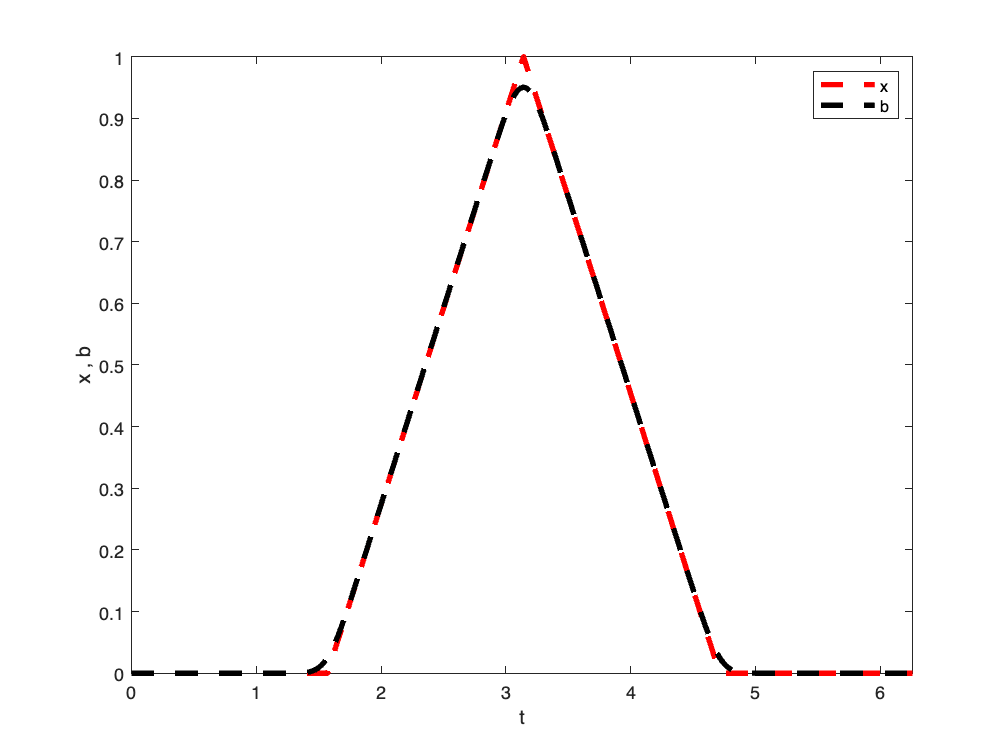

figure(2)
plot(t,x,'--r', LineWidth=3), hold on;
plot(t,b,'--k', LineWidth=3)
axis tight;
ylabel("x , b")
xlabel("t")
legend("x","b")

%%%%%%%%% (c) %%%%%%%%%%%%%%%

x_bar = A\b

x_bar =    0.077031751177694
  -0.052629260653967
  -0.007467077764012
   0.044717880290056
  -0.023568499443814
  -0.033696424976526
   0.068510349432990
  -0.043410189661611
  -0.020641257857149
   0.063869545997445


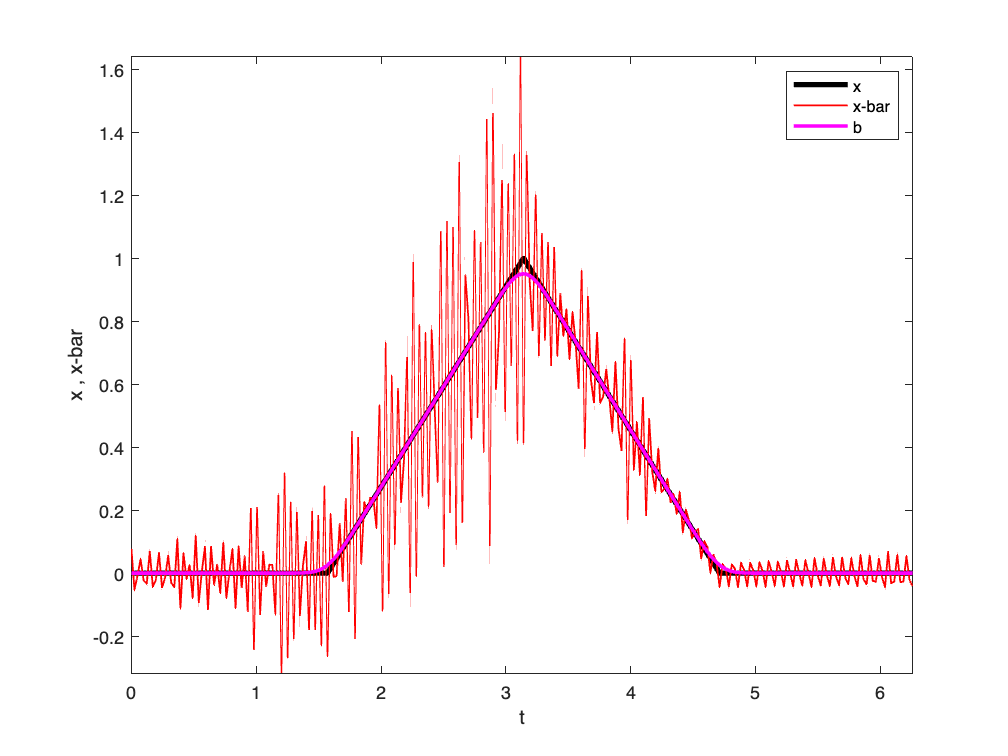

figure(3)
plot(t,x,'k', LineWidth=3), hold on;
plot(t,x_bar,'r', LineWidth=1), hold on
plot(t,b,'m', LineWidth=2)
axis tight;
ylabel("x , x-bar")
xlabel("t")
legend("x","x-bar","b")

x_bar appears to be very noisy. It looks substantially different from x.

%%%%%%%%% (d) %%%%%%%%%%%%%%%

[U,S,V] = svd(A);

nz = sum(S(1:size(S,1)+1:end)>10e-12);

v= [];u=[];
for i = 1:N
    if (S(i,i) > 10e-12)
        v = [v,V(:,i)];
        u = [u,U(:,i)];
    end
end
sigma =S(S>10e-12);
x_hat = lsq(u,v,b,sigma);

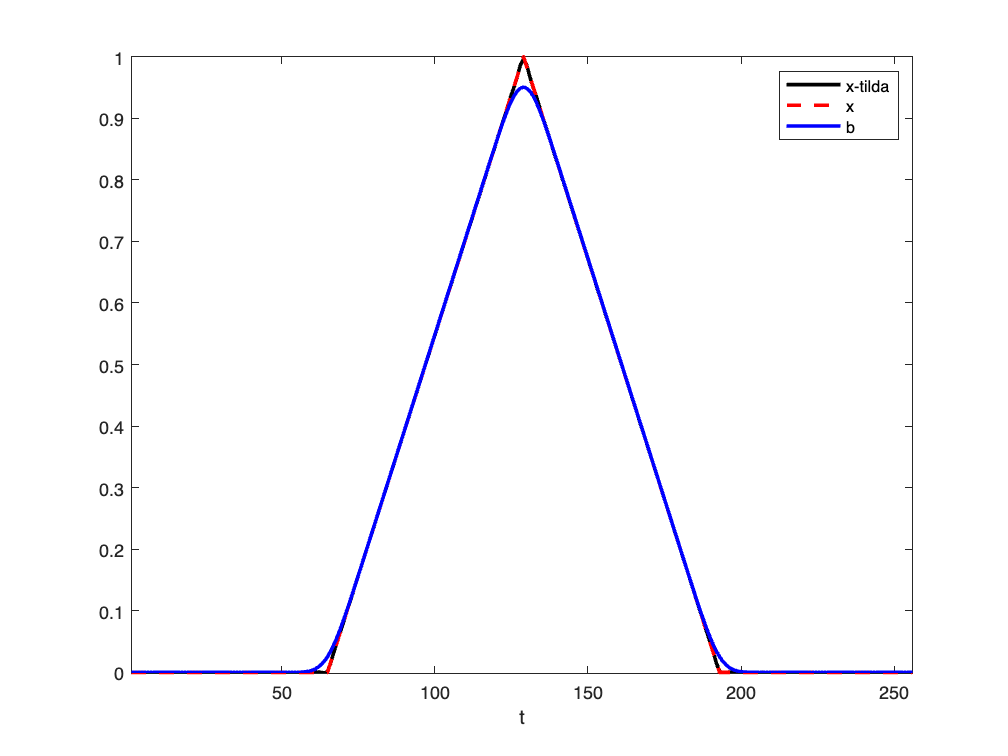

figure(4)
plot(1:N, x_hat,'k', LineWidth=2), hold on
plot(1:N, x,'--r', LineWidth=2)
plot(1:N,b,'b', LineWidth=2)
xlabel("t")
legend("x-tilda","x","b")
axis tight

x_tilda look more like x unlike x_bar. It approximates x better than b does.

%%%%%%%%% (e) %%%%%%%%%%%%%%%

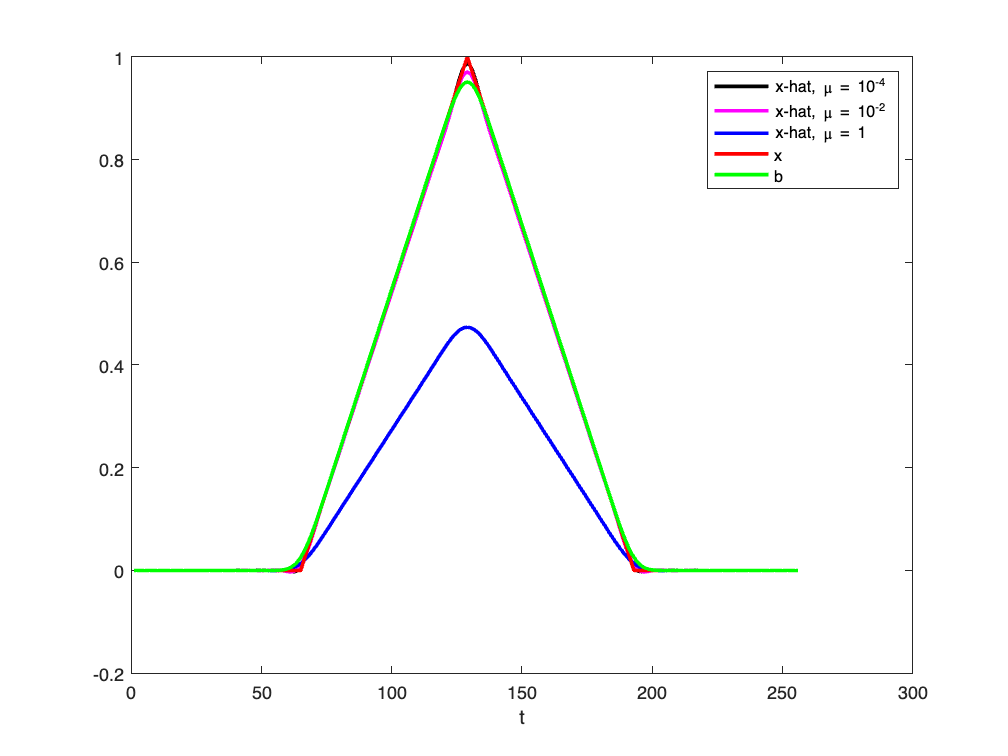

mu = [10^-4, 10^-2,1];

color = ['k','m','b'];
lgd = {'x-hat, \mu = 10^{-4}','x-hat, \mu = 10^{-2}','x-hat, \mu = 1'};
figure(5)
for j = 1:3
    x_hat = ridge_regression(u,v,b,sigma,mu(j));
    plot(1:N, x_hat,color(j), LineWidth=2), hold on
end
lgd{end + 1} = 'x';
lgd{end + 1} = 'b';
plot(1:N, x,'r', LineWidth=2)
plot(1:N, b,'g', LineWidth=2)
legend(lgd)
xlabel("t")

It can be obseerved that the x-hat approximates x better than b for small $\mu$. 

%%%%%%%%% (f) %%%%%%%%%%%%%%%

b = b + 1e-5*randn(N,1);
x_bar = A\b;

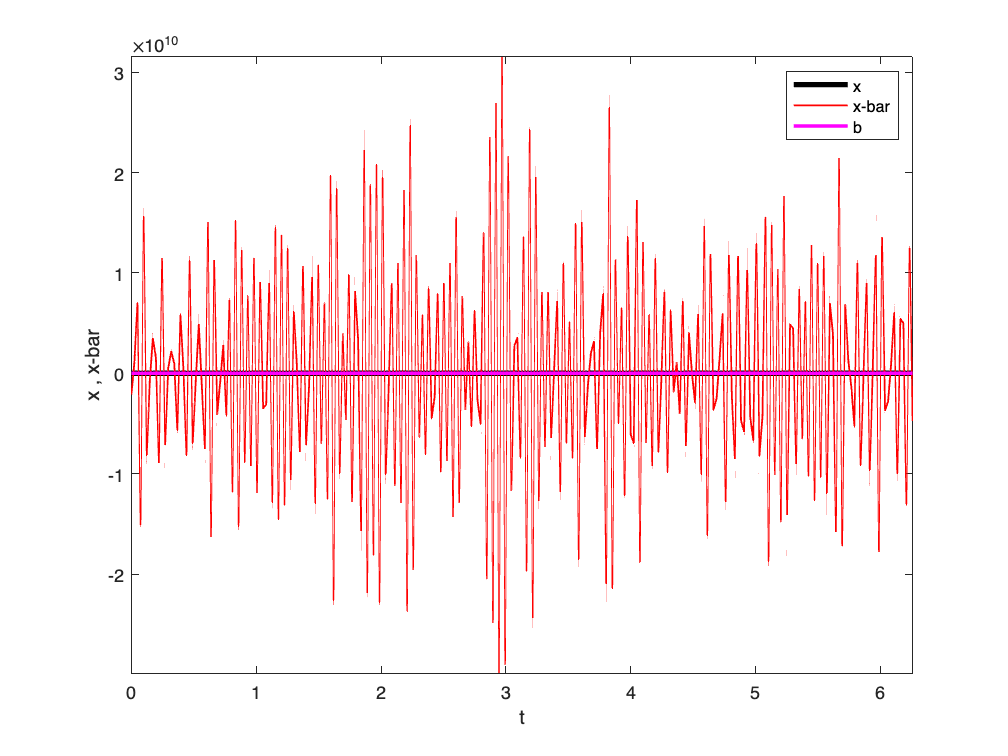

figure(6)
plot(t,x,'k', LineWidth=3), hold on;
plot(t,x_bar,'r', LineWidth=1), hold on
plot(t,b,'m', LineWidth=2)
axis tight;
ylabel("x , x-bar")
xlabel("t")
legend("x","x-bar","b")

x-bar is very noisy and its very different from x. Indeed the perturbation had a significant effect.

x_hat = lsq(u,v,b,sigma);

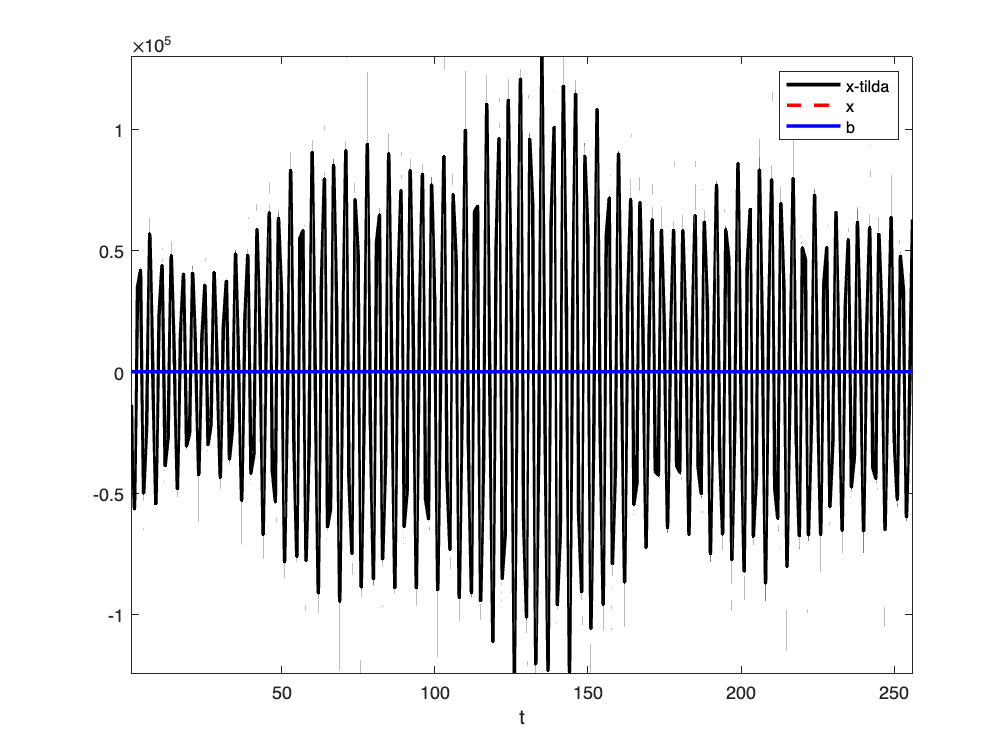

figure(7)
plot(1:N, x_hat,'k', LineWidth=2), hold on
plot(1:N, x,'--r', LineWidth=2)
plot(1:N,b,'b', LineWidth=2)
xlabel("t")
legend("x-tilda","x","b")
axis tight

x-tilda is also very noisy but with a smaller amplitude compared to x-bar.

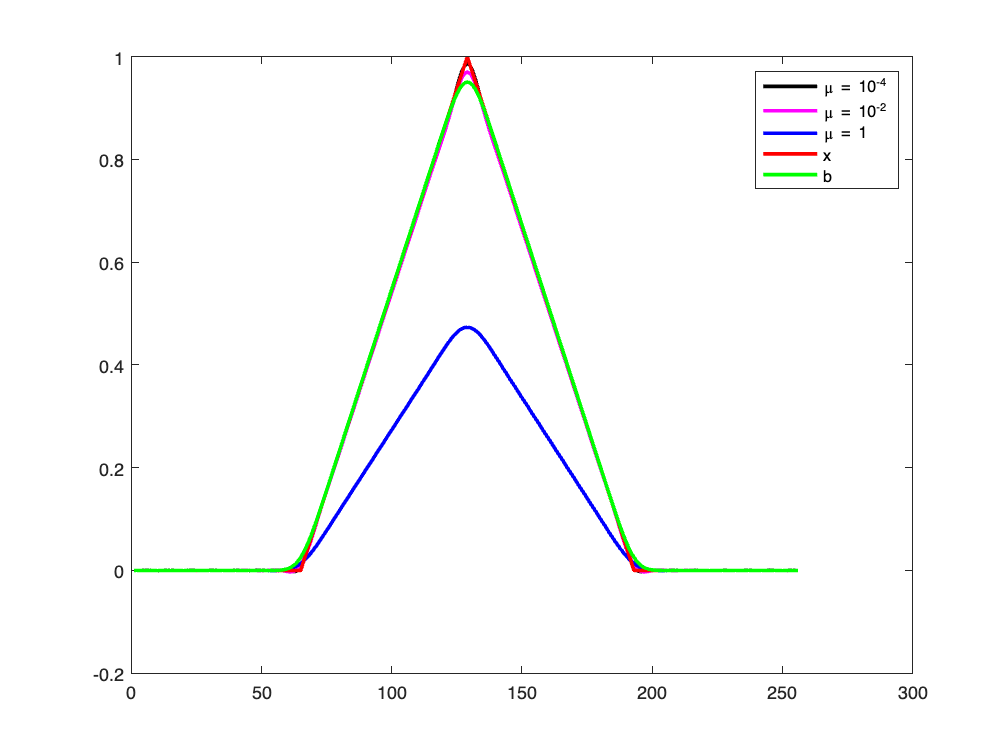

mu = [10^-4, 10^-2,1];

color = ['k','m','b'];
lgd = {'\mu = 10^{-4}','\mu = 10^{-2}','\mu = 1'};
figure(8)
for j = 1:3
    x_hat = ridge_regression(u,v,b,sigma,mu(j));
    plot(1:N, x_hat,color(j), LineWidth=2), hold on
end
lgd{end + 1} = 'x';
lgd{end + 1} = 'b';
plot(1:N, x,'r', LineWidth=2)
plot(1:N, b,'g', LineWidth=2)
legend(lgd)

It appears that x-hat is invariant of perturbation, as no change is observed in the plot compared to the unperturbed case.

**Question 4**

%%%%%%%%% (a) %%%%%%%%%%%%%%%%

%%%%%%%%%%% (b) %%%%%%%%%%%%%%%%%%%%%

A1 = zeros(21,21);
N=21;
for i=1:N
    for j = 1 : N
        if (i ==j)
            A1(i,j) = 1;
       elseif (i> j)
            A1(i,j) = -1;

       elseif (j == N)
            A1(i,j) =1;
       end
    end
end
[L,U,gf,p] = lupp(A1);
gf

gf =      1048576


function [L,U,gf,p] = lupp(A)
%lupp  Computes the LU decomposition of A with partial pivoting
%
%   [A,p] = lupp(A) Computes the LU decomposition of A with partial
%   pivoting using vectorization. The factors L and U are returned in the
%   output A, and the permutation of the rows from partial pivoting are
%   recorded in the vector p. Here L is assumed to be unit lower
%   triangular, meaning it has ones on its diagonal. The resulting
%   decomposition can be extracted from A and p as follows:
%       L = eye(length(LU))+tril(LU,-1);     % L with ones on diagonal
%       U = triu(LU);                        % U 
%       P = p*ones(1,n) == ones(n,1)*(1:n);  % Permutation matrix
%   A is then given as L*U = P*A, or P'*L*U = A.
%
%   Use this function in conjuction with backsub and forsub to solve a
%   linear system Ax = b.
A1 = A;
n = size(A,1);
p = (1:n)';

for k=1:n-1
    % Find the row in column k that contains the largest entry in magnitude
    [~,pos] = max(abs(A(k:n,k)));
    row2swap = k-1+pos;
    % Swap the rows of A and p (perform partial pivoting)
    A([row2swap, k],:) = A([k, row2swap],:);
    p([row2swap, k]) = p([k, row2swap]);
    % Perform the kth step of Gaussian elimination
    J = k+1:n;
    A(J,k) = A(J,k)/A(k,k);
    A(J,J) = A(J,J) - A(J,k)*A(k,J);
end
P = p*ones(1,n) == ones(n,1)*(1:n);
LU = P*A;
L = eye(length(LU))+tril(LU,-1);
U = triu(LU);
gf = max(abs(U),[],[1 2])/ max(abs(A1),[],[1 2]);
end

function [x_hat] = ridge_regression(u,v,b,sigma,mu)
nz = length(sigma);
x_hat = 0;
for i=1:nz
       q=sigma(i)/(sigma(i)^2 + mu);
       x_hat =x_hat + (q*(u(:,i)'*b)).*v(:,i);
end
end


function [x_hat] = lsq(u,v,b,sigma)
nz = length(sigma);
x_hat = 0;
for i = 1: nz
    x_hat =x_hat + ((u(:,i)'*b)./sigma(i)).*v(:,i);

end
end